# Creation, interrogation, and analysis of personalized microbiota models from the AGORA models through metagenomic data integration

## Author: Almut Heinken, National University of Ireland Galway and Federico Baldini, Luxembourg Centre for Systems Biomedicine 

## INTRODUCTION

This tutorial demonstrates the various function of the Microbiome Modeling Toolbox for the creation, interrogation, analysis, and stratification of personalized microbiome models. The tutorial consists of the following steps:

- Mapping files with abundances obtained from metagenomic sequencing data to the AGORA models

- Creating pan-models from AGORA on different taxonomical levels

- Building personalized models

- Computing net fecal uptake and secretion potential for all microbial metabolites

- Calculating subsystem abundances on the microbiome level

- Clustering and statistical analysis of net uptake and net secretion fluxes based on subgroups in samples

- Targeted analysis: computation of strain-level contributions in each sample to specific metabolites

- Targeted analysis: computation of shadow prices that reveal metabolite dependencies for a specific objective

- Integration of a host organism with personalized microbiome models

Please note that this tutorial uses as an example a small dataset (4 columns and 10 rows) with the purpose of demonstrating the functionalities of the pipeline. We recommend using high-performance computing clusters when assembling and simulating from bigger datasets.

## DRIVER

The  pipeline driver script cobratoolbox/papers/2018_microbiomeModelingToolbox/startMgPipe.m contains the neccessary inputs to run mgPipe for your dataset. Replace the input variables in startMgPipe with your own dataset and modifiy as needed.

## Initialize the COBRA Toolbox

initCobraToolbox(false)

Set a solver (recommended: ibm_cplex)

solverOK=changeCobraSolver('ibm_cplex','LP');

## Prepare input data and models

We first set the paths to input and output files change directory to where the tutorial is located

tutorialPath = fileparts(which('tutorial_mgPipe'));


100  451M    0  451M    0     0  6225k      0 --:--:--  0:01:14 --:--:-- 3815k
100  455M    0  455M    0     0  6196k      0 --:--:--  0:01:15 --:--:-- 3871k
100  458M    0  458M    0     0  6165k      0 --:--:--  0:01:16 --:--:-- 3831k
100  462M    0  462M    0     0  6136k      0 --:--:--  0:01:17 --:--:-- 3870k
100  466M    0  466M    0     0  6102k      0 --:--:--  0:01:18 --:--:-- 3854k
100  469M    0  469M    0     0  6073k      0 --:--:--  0:01:19 --:--:-- 3835k
100  473M    0  473M    0     0  6045k      0 --:--:--  0:01:20 --:--:-- 3778k
100  477M    0  477M    0     0  6020k      0 --:--:--  0:01:21 --:--:-- 3804k
100  480M    0  480M    0     0  5989k      0 --:--:--  0:01:22 --:--:-- 3733k
100  484M    0  484M    0     0  5963k      0 --:--:--  0:01:23 --:--:-- 3783k
100  488M    0  488M    0     0  5934k      0 --:--:--  0:01:24 --:--:-- 3734k
100  491M    0  491M    0     0  5908k      0 --:--:--  0:01:25 --:--:-- 3705k
100  495M    0  495M    0     0  5887k      0 --:--

ans = 0

cd(tutorialPath);

We will use the AGORA resource (Magnusdottir et al., Nat Biotechnol. 2017 Jan;35(1):81-89) in this tutorial. AGORA version 1.03 is available at [https://github.com/VirtualMetabolicHuman/AGORA](https://github.com/VirtualMetabolicHuman/AGORA). Download AGORA and place the models into a folder.

Starting parallel pool (parpool) using the 'local' profile ...
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed to a character array.
Each model.subSystems{x} has been changed

There were some old style fields in the model which could not be converted. Loading the old model

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (76976,34281)
 >> Only 314 reactions of 34281 are solved (~ 0.92%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).
 

 >> The number of reactions retrieved is 314
 >> Log files will be stored at /Users/mspg/Documents/GitHub/cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Thu Feb  4 10:54:21 2021
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you expect.

        -- Minimization (iRound = 0). Number of reactions: 314. - printLevel 1
        -- Maximization (iRound = 1). Number of reactions: 314.
 -- End time:    

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (76976,34281)
 >> Only 314 reactions of 34281 are solved (~ 0.92%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).
 

 >> The number of reactions retrieved is 314
 >> Log files will be stored at /Users/mspg/Documents/GitHub/cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Thu Feb  4 11:15:25 2021
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you expect.

        -- Minimization (iRound = 0). Number of reactions: 314. - printLevel 1
        -- Maximization (iRound = 1). Number of reactions: 314.
 -- End time:    

There were some old style fields in the model which could not be converted. Loading the old modelStarting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans = 

 Pool with properties: 

            Connected: true
           NumWorkers: 4
              Cluster: 

 -- End time:     Thu Feb  4 12:09:18 2021


 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (68317,30466)
 >> Only 314 reactions of 30466 are solved (~ 1.03%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).
 

 >> The number of reactions retrieved is 314
 >> Log files will be stored at /Users/mspg/Documents/GitHub/cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Thu Feb  4 12:09:20 2021
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you expect.

        -- Minimization (iRound = 0). Number of reactions: 314. - printLevel 1
        -- Maximization (iRound = 1). Number of reactions: 314.
 -- End time:    

There were some old style fields in the model which could not be converted. Loading the old modelStarting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans = 

 Pool with properties: 

            Connected: true
           NumWorkers: 4
              Cluster: 

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (77298,34421)
 >> Only 314 reactions of 34421 are solved (~ 0.91%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 1 / 4 (LoopID = 1) <> [1, 79] / [77298, 314].
 >> Number of reactions given to the worker: 79 
 >> The number of reactions re

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (77298,34421)
 >> Only 314 reactions of 34421 are solved (~ 0.91%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 3 / 4 (LoopID = 3) <> [159, 236] / [77298, 314].
 >> Number of reactions given to the worker: 78 
 >> The number of reactions

There were some old style fields in the model which could not be converted. Loading the old model

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (65906,29381)
 >> Only 314 reactions of 29381 are solved (~ 1.07%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 2 / 4 (LoopID = 2) <> [80, 158] / [65906, 314].
 >> Number of reactions given to the worker: 79 
 >> The number of reactions 

 > The version of CPLEX is 129.



-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.A. (coupled) - Generalized
 >> The number of arguments is: input: 6, output 2.
 >> Size of stoichiometric matrix: (65906,29381)
 >> Only 314 reactions of 29381 are solved (~ 1.07%).
 >> 0 reactions out of 314 are minimized (0.00%).
 >> 0 reactions out of 314 are maximized (0.00%).
 >> 314 reactions out of 314 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 3 / 4 (LoopID = 3) <> [159, 236] / [65906, 314].
 >> Number of reactions given to the worker: 78 
 >> The number of reactions

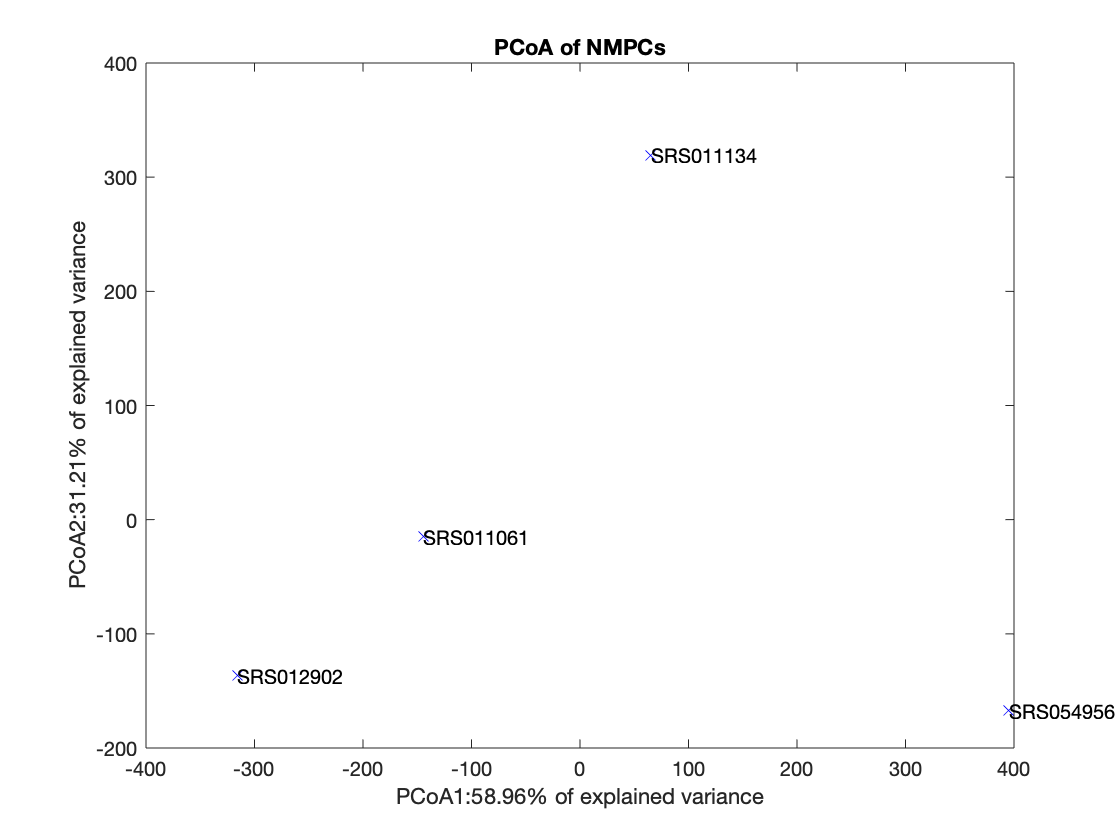

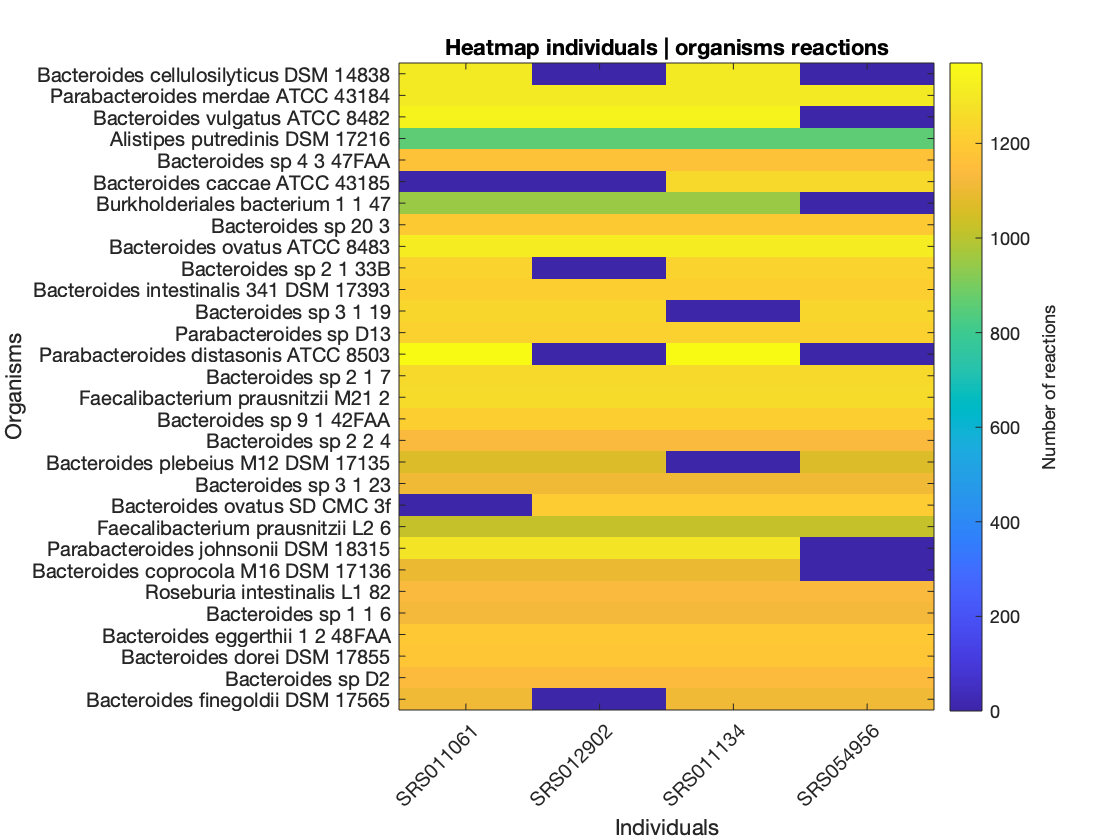

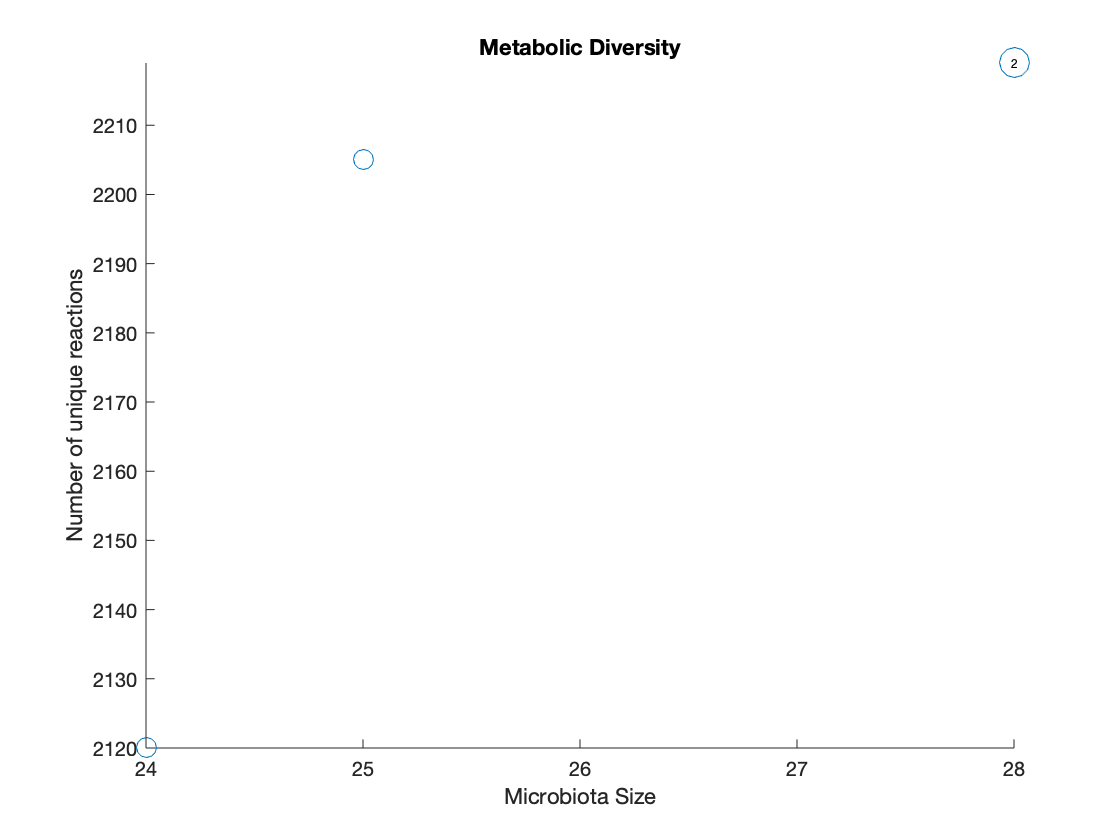

system('curl -LJO https://github.com/VirtualMetabolicHuman/AGORA/archive/master.zip')

unzip('AGORA-master')
modPath = [pwd filesep 'AGORA-master' filesep 'CurrentVersion' filesep 'AGORA_1_03' filesep' 'AGORA_1_03_mat'];

path where to save results

mkdir('Results');

resPath = [tutorialPath filesep 'Results'];

path to and name of the file with dietary information. Here, we will use an "Average European" diet that is located in the folder

cobratoolbox/papers/2018_microbiomeModelingToolbox/input

The folder also contains various other simulated diets, e.g., Vegan, gluten-free.

 > Models will be read from: /Users/mspg/Documents/GitHub/cobratoolbox/tutorials/analysis/microbiomeModelingToolbox/AGORA-master/CurrentVersion/AGORA_1_03/AGORA_1_03_mat
 > Results will be stored in: /Users/mspg/Documents/GitHub/cobratoolbox/tutorials/analysis/microbiomeModelingToolbox/Results/
 > Microbiome Toolbox pipeline initialized successfully.
Plain csv input format: adding index for internal purposes
mapping file found: loading from resPath and skipping [PART1] analysis
global setup file found: loading from resPath and skipping [PART2.1] analysis
microbiota model file found: skipping model creation for this sample
microbiota model file found: skipping model creation for this sample
microbiota model file found: skipping model creation for this sample
microbiota model file found: skipping model creation for this sample
simulations already done, file found: loading from resPath


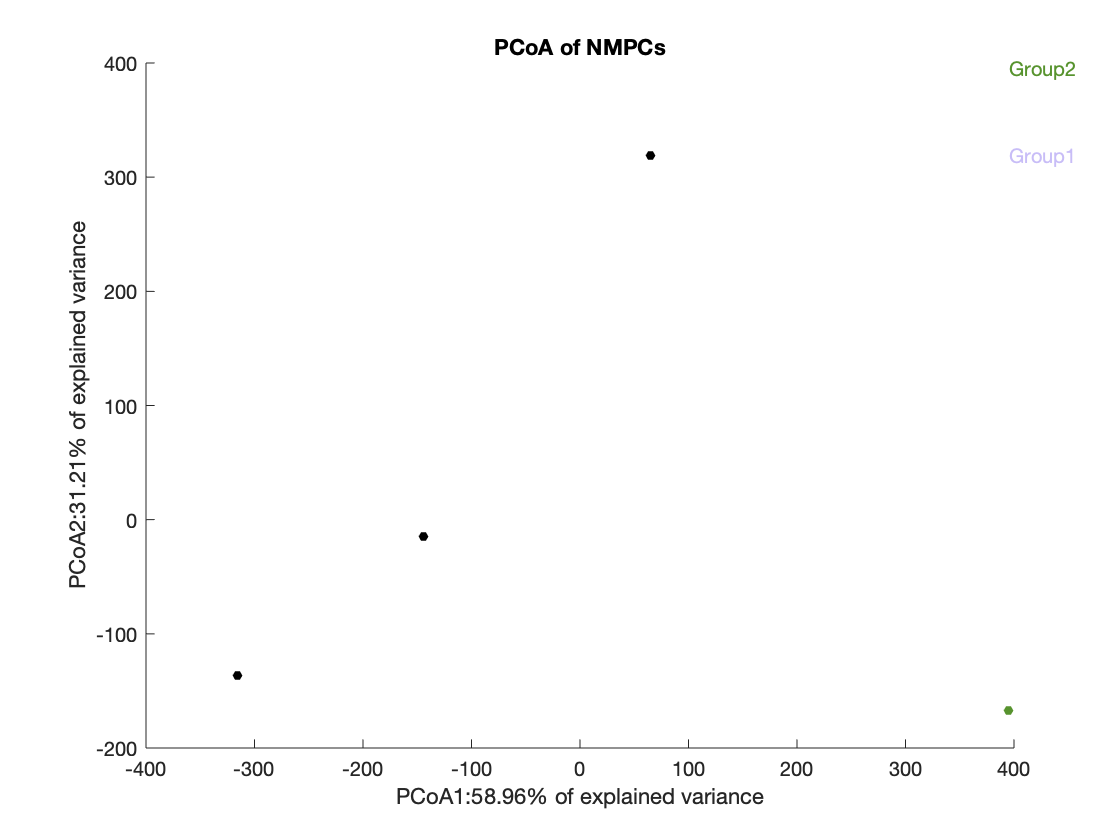

dietFilePath='AverageEuropeanDiet';

## Preparing the input file with normalized abundances

Preparing an input file suitable for mgPipe requires mapping the organisms to the nomenclature of the AGORA models. A function that can help with this is available in the COBRA Toolbox.

For an example of how to map metagenomic sequences to AGORA models, enter the following code:

system('curl -LJO https://www.ebi.ac.uk/metagenomics/api/v1/studies/MGYS00001248/pipelines/3.0/file/SRP065497_taxonomy_abundances_v3.0.tsv')

[translatedAbundances,normalizedAbundances,unmappedRows] = translateMetagenome2AGORA('SRP065497_taxonomy_abundances_v3.0.tsv','Species');

*translateMetagenome2AGORA* translates the output of common sequencing pipelines (e.g., MetaPhlAn) to the names of the AGORA models. However, the function may not work for the nomenclature of some input file types it has never been tested on. Manual inspection to map taxa may still be needed. Inspect the output variable unmappedRows to check for mismatches in nomenclature. Such mismatches can be correcting by adding nomenclature corrections after line 115 of the *translateMetagenome2AGORA *function. It is requested to also submit such nomenclature corrections as a pull request.

To normalize the relative abundances from the input file that had been mapped to AGORA organisms, run the function normalizeCoverage. It is recommended to set the input variable cutoff (e.g., 0.0001), which removes all strains below a certain normalized relative abundance in a sample. Removing taxa with very low normalized coverage will result in faster simulations.

cutoff = 0.0001;

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
411476.11.peg.1032
411476.11.peg.1036
411476.11.peg.1037
411476.11.peg.1041
411476.11.peg.1044
411476.11.peg.1049
411476.11.peg.105
411476.11.peg.1050
411476.11.peg.1053
411476.11.peg.1054
411476.11.peg.1055
411476.11.peg.1058
411476.11.peg.1067
411476.11.peg.1069
411476.11.peg.1070
411476.11.peg.1071
411476.11.peg.1072
411476.11.peg.1073
411476.11.peg.1077
411476.11.peg.1087
411476.11.peg.1098
411476.11.peg.110
411476.11.peg.111
411476.11.peg.1117
411476.11.peg.1119
411476.11.peg.112
411476.11.peg.1120
411476.11.peg.1121
411476.11.peg.1122
411476.11.peg

[normalizedCoverage,abunFilePath] = normalizeCoverage(translatedAbundances,cutoff);

The file normalizedCoverage.csv now contains relative normalized abundances mapped to the nomenclature of AGORA that could serve as input for mgPipe. The output variable abunFilePath can directly serve as input for the corresponding input variable in initMgPipe. 

## Creating pan-models from AGORA on different taxonomical levels

As the abundances in this example are provided on the species level, the AGORA reconstructions, which are strain-specific, cannot serve as direct input. To enable the creation of personalized microbiome models from species-level relative abundances (or alternatively genus- or family-level), pan-models need to be created from AGORA. The following code performs this on the species level. To create pan-models on other species level up to phylum, modify the input variable taxonLevel.

panPath=[tutorialPath filesep 'panSpeciesModels'];

mkdir(panPath)

taxonLevel='Species';

createPanModels(modPath,panPath,taxonLevel);

By setting panPath as the input variable modPath for initMgPipe, personalized microbiome models for the samples from the above study with the EMBL-EBI accession ID SRP065497 could now readily  be created and interrogated through mgPipe. As this would be too computationally intensive for the purpose of this tutorial, this will not be performed here.

## Building personalized models 

While personalized models are built by executing the function *initMgPipe*, the following steps are performed automatically.

- Classicial multidimensional scaling (PCoA) of the relative abundances is performed.

- The diversity in terms of organisms present ine ach sample is plotted.

- The relatives abundances of each reaction present in at least one organism in each sample is computed (value of 0 to 1 with 1 indicating that every organism in the sample has the reaction).

First, we set the path and the name of the file from which to load the abundances. For this tutorial, to reduce the time of computations, we will use a reduced version of the example file (normCoverageReduced.csv) provided in the folder Resources: only 4 individuals and 10 strains will be considered.

abunFilePath='normCoverageReduced.csv';

i = 1

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.


For the creation of personalized models, mgPipe offers two strategies that are selected in the input variable buildSetupAll. By default, a global metabolic model (setup) is constructed containing all the microbes listed in the study. Personalized models are built for each sample by pruning the global model. As another option, which is recommended for studies with 300 or more microbes total, personalized models can be built serially. In both cases, a community biomass reaction is built from the relative abundances in each sample.

By default, mgPipe will subsequently compute the metabolic profiles of each personalized model. Briefly, the chosen dietary regime is implemented and the total net uptake and net secretion potential for each metabolite that can be transported by at least one microbe in the study is computed for each personalized model. The PCoA of computed fluxes is also plotted. If this is not neccessary and targeted analyses are instead planned (see later sections in the tutorial), the computation can be disabled through the input variable fvaType. In either case, the personalized models with dietary constraints implemented can be exported through the variable saveConstrModels. Exporting the constrained models will also enable customized analyses outside mgPipe.

To define whether flux variability analysis to compute the metabolic profiles should be performed, and which FVA function should be used, set the input variable fvaType. Allowed inputs are 'fastFVA', 'fluxVariability', 'none'. Please note that it is highly recommended to use fastFVA as this drastically reduces computation times in large datasets. For the sake of this tutorial, we will use fluxVariability.

fvaType = 'fluxVariability';

## Setting optional inputs

Next inputs will define:

- name of the objective function of organisms

- whether to create the personalized models by pruning a global setup model (default) or one by one

- number of cores to use for the pipeline execution

- if stratification criteria (e..g., cases and controls) are available for the samples

- if to simulate also a rich diet

- if to save models with diet constraints implemented

- the lower bound in mmol/person/day set on the community biomass reaction

- whether already existing simulation results should be overwritten

- whether the simulated dietary regime should be supplemented with compounds typically found in the gut thus mimicking the human intestinal environment

The following setting should work for almost any system, but please check carefully to be sure these options are valid for you. A more detailed description of these variables is available in the documentation. 

The same inputs need to be set in the driver file StartMgPipe when running mgPipe outside of this tutorial or directly in the "initMgPipe" function.

OPTIONAL INPUTS

path to csv file for stratification criteria (if empty or not existent no criteria is used)

infoFilePath = '';

path to a model of the host (e.g., human) to be joined with the microbiomes (default: no host)

hostPath = '';

name of objective function of organisms, default='EX_biomass(e)'

objre = 'EX_biomass(e)';

strategy used to build personalized models. If true: create a global setup model that is pruned, if false, create each personalized model one by one. The latter is recommended if there are 300 or more individual organisms.

buildSetupAll = true;

if to save models with diet constrains implemented (default=false)

saveConstrModels = true;

number of cores dedicated for parallelization (default=2)

numWorkers = 4;

 to enable also rich diet simulations (default=false)

rDiet = false;

to enable personalized diet simulations (default=false)

pDiet = false;

to manually set the lower bound on flux through the community biomass reaction (default=0.4 mmol/person/day)

lowerBMBound = 0.4;

to set whether existing simulation results are rewritten (default=false)

repeatSim = false;

to set if the input medium should be adapted through the adaptVMHDietToAGORA function or used as is (default=true)                  

adaptMedium = true;

## Pipeline run

Calling the function initMgPipe will execute Part 1 to 3 of the pipeline.

[init, netSecretionFluxes, netUptakeFluxes, Y] = initMgPipe(modPath, abunFilePath, fvaType, 'resPath', resPath, 'dietFilePath', dietFilePath, 'infoFilePath', infoFilePath, 'hostPath', hostPath, 'objre', objre, 'buildSetupAll', buildSetupAll, 'saveConstrModels', saveConstrModels, 'numWorkers', numWorkers, 'rDiet', rDiet, 'pDiet', pDiet, 'lowerBMBound', lowerBMBound, 'repeatSim', repeatSim, 'adaptMedium', adaptMedium);

## Computed outputs

- **Metabolic diversity** The number of mapped organisms for each individual compared to the total number of unique reactions (extrapolated by the number of reactions of each organism).Please, note that bigger circles with a number inside represent overlapping individuals for metabolic diversity. 

- **Classical multidimensional scaling of each individual reactions repertoire**

**If flux variability analysis is performed and net uptake and secretion potential are computed:**

Flux Variability analysis for all the exchange reactions of the diet and fecal compartment are performed and temporarily saved in a file called "simRes". Specifically what is temporarily saved is:

- **fvaCt** a cell array containing min flux through uptake and max trough secretion exchanges

- **nsCT** a cell array containing max flux through uptake and min trough secretion exchanges

- **presol** an array containing the value of objectives for each microbiota model with rich and selected diet

- **inFesMat** cell array containing the names of the microbiota models that reported an infeasible status when solved for their objective 

Finally, the net uptake and secretion potential are computed in a metabolite resolved manner and saved in the output variables 'netSecretionFluxes' and netUptakeFluxes, and the files 'netSecretionFluxes.csv' and 'netUptakeFluxes.csv' in the results folder. They indicate the maximal uptake and production, respectively, of each metabolite and are computed as the absolute value of the sum of the maximal secretion flux with the maximal uptake flux. The similarity of metabolic secretion profiles (using the net secretion potential as features) between individuals is also evaluated with classical multidimensional scaling. 

In the export of models with dietary constraints is desired, they will be found in the folder constrModelsPath.

## Calculating subsystem abundances

The out file "reactions.csv" in the Results folder cotnain the relative abundance of each reaction in each sample. A description of each reaction can be found by searching for the reaction ID in the file

cobratoolbox/papers/2021_demeter/input/ReactionDatabase.txt

or on the Virtual Metabolic Human website (https://www.vmh.life/).

For a more convenient overview of pathways altered in their relative abundances across samples, the relative abundances can also be calculated for each sample on the subsystem level by entering the code

reactionAbundancePath=[resPath filesep 'reactions.csv'];
subsystemAbundance = calculateSubsystemAbundance(reactionAbundancePath);

The calculated subsystem abundances can be found in the output variable subsystemAbundance and in the file "SubsystemAbundance.txt". A subsystem abundance of 1 indicates that each reaction in the subsystem found in at least one sample is present at a relative abundance of 1 in the sample.

## Stratification of samples

If metadata for the analyzed samples is available (e.g., disease state), the samples can be stratified based on this classification. To provide metadata, prepare an input file as in the example 'sampInfo.csv'. The path to the file with sample information needs to be provided as the variable infoFilePath. Note that the group classification into groups in sampInfo.csv is arbitrary and not biological meaningful.

infoFilePath='sampInfo.csv'; 
saveConstrModels = false;

[init, netSecretionFluxes, netUptakeFluxes, Y] = initMgPipe(modPath, abunFilePath, fvaType, 'resPath', resPath, 'dietFilePath', dietFilePath, 'infoFilePath', infoFilePath, 'hostPath', hostPath, 'objre', objre, 'buildSetupAll', buildSetupAll, 'saveConstrModels', saveConstrModels, 'numWorkers', numWorkers, 'rDiet', rDiet, 'pDiet', pDiet, 'lowerBMBound', lowerBMBound, 'repeatSim', repeatSim, 'adaptMedium', adaptMedium);

## Statistical analysis and plotting of generated fluxes

If sample information as in sampInfo.csv is provided (e.g., healthy vs. disease state), statistical analysis can be performed to identify whether net secretion fluxes, net uptake fluxes, and reaction abundances can be performed. If the analyzed samples can be divided into two groups, Wilcoxon rank sum test will be used. If there are three or more groups, Kruskal-Wallis test will be performed. Note that no statistically significant differences will be found in the tutorial example due to the small sample sizes. Moreover, violin plots that show the computed fluxes separate by group will be generated.

Define the input variables. Path to file with sample information (required)

infoFilePath='sampInfo.csv';

Header in the file with sample information with the stratification to  analyze (if not provided, the second column will be chosen by default)

sampleGroupHeaders={'Group'};

sampleGroupHeaders can contain more than one entry if multiple columns  with sample information (e.g., disease state, age group) should be analyzed.

path with results of mgPipe that will be analyzed

resPath = [tutorialPath filesep 'Results'];

define where results will be saved (optional, default folders will be generated otherwise)

statPath = [tutorialPath filesep 'Statistics'];
violinPath = [tutorialPath filesep 'ViolinPlots'];

**To perform the statistical analysis and save the results, enter the code**

analyzeMgPipeResults(infoFilePath,resPath,'statPath', statPath, 'violinPath', violinPath, 'sampleGroupHeaders', sampleGroupHeaders);

Afterwards, the results of the statistical analysis will be available in the folder "Statistics". The files ending in "Statistics.txt" contain the calculated p-values and test results. If there are any fluxes or abundances that significantly differed between groups, there will be files ending in "significantFeatures.txt" listing only these instances. Created violin plots will be found in the folder "ViolinPlots". There will be an image in png and pdf format for each predicted metabolite's uptake and secretion potential. There will also be a file ending in "All_plots.pdf" containing all plots.

## Targeted analysis: Strain-level contributions to metabolites of interest

For metabolites of particular interest (e.g., for which the community-wide secretion potential was significantly different between disease cases and controls), the strains consuming and secreting the metabolites in each sample may be computed. This will yield insight into the contribution of each strain to each metabolite. Note that for metabolites for which the community wide secretion potential did not differ, the strains contributing to metabolites may still be significantly different.

The first step for the preparation of targeted analyses is the export of models that ahd already been constrained with the simulated dietary regime. This had already been done above through the saveConstrModels input in mgPipe above. Now, will set the input variable modPath to the folder with personalized models constrained with the simulated diet.

modPath = constrModelsPath;

We will define a list of metabolites to analyze. As an example, we will take acetate and formate.

metList = {'ac','for'};

create a new folder where strain contributions will be saved

mkdir([tutorialPath filesep 'StrainContributions']);
contPath = [tutorialPath filesep 'StrainContributions'];

[minFluxes,maxFluxes,fluxSpans] = predictMicrobeContributions(modPath, 'resPath', contPath, 'dietFilePath', dietFilePath, 'metList', metList, 'numWorkers', numWorkers, 'lowerBMBound', lowerBMBound, 'adaptMedium', adaptMedium);

The output 'minFluxes' shows the fluxes in the reverse direction through all internal exchange reactions that had nonzero flux for each analyzed metabolite. The output 'maxFluxes' shows the corresponding forward fluxes. 'fluxSpans' shows the distance between minimal and maximal fluxes for each internal exchange reaction with nonzero flux for each metabolite.

Afterwards, statistical analysis of the strain contributions can also be performed.

analyzeMgPipeResults(infoFilePath,contPath, 'statPath', statPath, 'violinPath', violinPath, 'sampleGroupHeaders', sampleGroupHeaders);

## Targeted analysis: Computation of shadow prices for secreted metabolites of interest

Shadow prices are routinely retrieved with each flux balance analysis solution. Briefly, the shadow price is a measurement for the value of a metabolite towards the optimized objective function, which indicates whether the flux through the objective function would increase or decrease when the availability of this metabolite would increase by one unit (Palsson B. Systems biology : properties of reconstructed networks). For microbiome community models created through mgPipe, this will enable us to determine which metabolites are bottlenecks for the community's potential to secrete a metabolite of interest. This was performed for bile acids in Heinken et al., Microbiome (2019) 7:75. However, any other reaction in the personalized model (or any other model) can also serve as the input.

We will compute the shadow prices for acetate and formate as an example.

objectiveList={
    'EX_ac[fe]'
    'EX_for[fe]'
    };

Here, we will compute all shadow prices that are nonzero. Thus, this include both metabolites that would increase and decrease the flux through the objective function if their availability was increased. Note that the definition of the shadow price depends on the solver.  To check the shadow price definitions for each solver, run the test script testDualRCostDefinition.

SPDef = 'Nonzero';

create a new folder where shadow prices will be saved

mkdir([tutorialPath filesep 'ShadowPrices']);
spPath = [tutorialPath filesep 'ShadowPrices'];

[objectives,shadowPrices]=analyseObjectiveShadowPrices(modPath, objectiveList, 'resultsFolder', spPath, 'SPDef', SPDef, 'numWorkers', numWorkers, 'dietFilePath', dietFilePath, 'lowerBMBound', lowerBMBound, 'adaptMedium', adaptMedium);

Similar to the previous results, we can also perform statistical analysis on the computed shadow prices.

analyzeMgPipeResults(infoFilePath,spPath,'statPath', statPath, 'violinPath', violinPath,'sampleGroupHeaders', sampleGroupHeaders);

## Using mgPipe to model host-microbiome co-metabolism

If desired, the sample-specific microbiome models created by mgPipe can also be joined with a model of the host, e.g., with the human reconstruction Recon3D. Let us create the same four microbiome models as before joined with Recon3D.

system('curl -LJO https://www.vmh.life/files/reconstructions/Recon/3D.01/Recon3D_301.zip')
unzip('Recon3D_301')
hostPath = [pwd filesep 'Recon3D_301' filesep 'Recon3DModel_301.mat'];

Since host metabolites can now enter from the host model itself, the  adaptMedium input can be set to false.                 

adaptMedium = false; 

If a host model is entered, it is also highly recommended to enter the host biomass reaction to generate coupling constraints for the host.

hostBiomassRxn = 'biomass_reaction';

The upper bound on the flux through the host biomass reaction can also be constrained by entering the input variable hostBiomassRxnFlux (default: 1).

hostBiomassRxnFlux = 1;

For the sake of this tutorial, we will only create personalized models combined with Recon3D and constrained with the Average European diet, not run FVA again.

fvaType = 'none';

Run the pipeline to create personalized host-microbiome models.

[init, netSecretionFluxes, netUptakeFluxes, Y] = initMgPipe(modPath, abunFilePath, fvaType, 'resPath', resPath, 'dietFilePath', dietFilePath, 'infoFilePath', infoFilePath, 'hostPath', hostPath, 'hostBiomassRxn', hostBiomassRxn, 'hostBiomassRxnFlux', hostBiomassRxnFlux, 'objre', objre, 'buildSetupAll', buildSetupAll, 'saveConstrModels', saveConstrModels, 'numWorkers', numWorkers, 'rDiet', rDiet, 'pDiet', pDiet, 'lowerBMBound', lowerBMBound, 'repeatSim', repeatSim, 'adaptMedium', adaptMedium);